filename1 = "y_test.csv";
table1 = readtable(filename1);
test = table2array(table1);

filename = "y_pred.csv";
table = readtable(filename);
pred_raw = table2array(table)

pred_raw =    93.9116  145.0573  155.3977  174.3145  174.1556
  121.9999   97.6556   96.4702  170.6854  170.6854
  141.2969   63.8689   54.9331  171.1812  170.9151
  142.2014   61.2989   51.9124  171.1442  171.1442
  142.2356   61.8460   52.4703  171.1246  171.1246
   85.2146  158.4322  172.4181  174.6575  174.6575
  130.0308  151.3179  155.7447  173.5447  173.2264
  117.1109  158.7249  167.2092  175.1055  174.7867
  143.5537   64.8635   53.9153  171.1798  171.1798
  139.7324   66.8584   58.5773  171.2357  170.9910


pred_filt = zeros(size(pred_raw));
pred_env = zeros(size(pred_raw))

pred_env =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


fc = 10;
fs = 2000;
[b,a] = butter(2,fc/(fs/2),"low")

b = 1.0e-03 *

    0.2414    0.4827    0.2414


a =     1.0000   -1.9556    0.9565



for i = 1:5
    pred_filt(:,i) = filter(b,a,pred_raw(:,i));
    [x,pred_env(:,i)] = envelope(pred_raw(:,i),200,'peak');
end

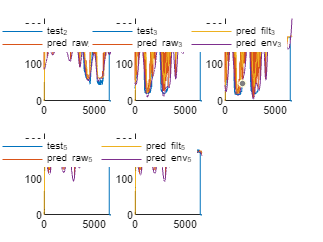

clf
figure
for i = 1:5
    subplot (2,3,i)
    hold on
    plot(test(:,i))
    plot(pred_raw(:,i))
    plot(pred_filt(:,i))
    plot(pred_env(:,i))
    ylim([0 225])
    legend("test_"+i, "pred raw_"+i, "pred filt_"+i , "pred env_"+i, ...
        'Location','north','NumColumns',2)
    legend('boxoff')
    hold off
end